# WorkSheet 4:

Problem 1:

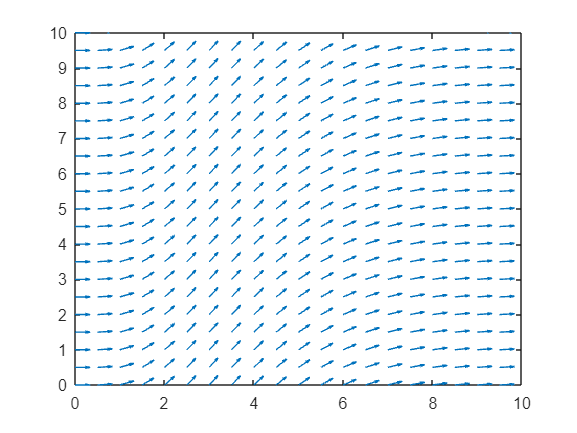

% This was used to test myQuiver and see if it actually worked or not
x0=0;
x1=10;
y0=0;
y1=10;
h=0.5;
scale=0.5;
dy=@(x,y) x.^3;
dx=@(x,y) exp(x);
myQuiver(x0,x1,y0,y1,h,dy,dx,scale);
xlim([0,10])
ylim([0,10])

Problem 2:

% Part a: solve the ODE of 2x*dy/dx-3y = 9x^3
% the solution to the problem: y = 3x^3 + Cx^3/2
% Where C can be any real value in the plane

% Part b:
f_0 = @(t,C)3.*t.^3+C*t.^(3/2);
x = linspace(-2.5,2.5);
plot(x,f_0(x,-5))

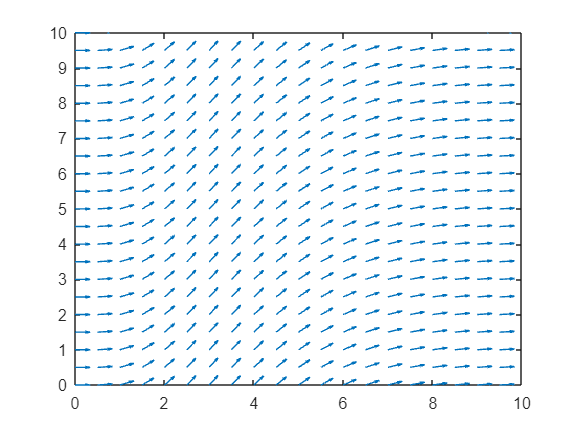

xlabel('x-values')
ylabel('y-values')
title('Solutions to y = 3x^3 + Cx^(3/2)')
legend('C = -5','location', 'best')
axis square

% Part c,d,e
hold on
x0=-5;
x1=5;
y0=-5;
y1=5;
h=0.5;
scale=0.5;
dy = @(x,y) 3.*y + 9*x.^3;
dx = @(x,y) 2.*x;
myQuiver(x0,x1,y0,y1,h,dy,dx,scale);
xlim([-5,5]);
ylim([-5,5]);
hold off
xlabel('x-values')
ylabel('y-values')
title('Plotting General Solution of ODE onto its Slope Field')

Problem 3:

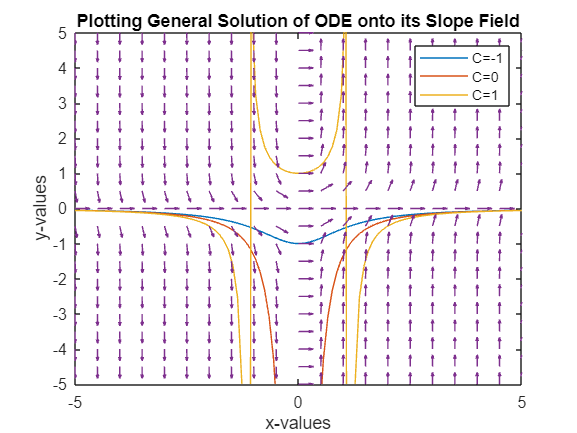

% Part a: the solution to the ODE is y = 1/(C-3.*x.^2)
% Note that we will have to rearrange the equation later on to make it
% implicit so that we avoid asymptotes in the graph
f_0 = @(t,C)1./(C-3.*x.^2);
x = linspace(-5,5);


% parts b, c, and d
for j=-1:1
    plot(x,f_0(x,j))
    hold on 
end
x0=-5;
x1=5;
y0=-5;
y1=5;
h=0.5;
scale=0.5;
dy = @(x,y) 6.*x.*y.^2;
dx = @(x,y) 1;
myQuiver(x0,x1,y0,y1,h,dy,dx,scale);
xlim([-5,5]);
ylim([-5,5]);
hold off
xlabel('x-values')
ylabel('y-values')
title('Plotting General Solution of ODE onto its Slope Field')
legend('C=-1','C=0', 'C=1')